addpath('../Data/raw_data/')
load('lfp.mat');
load('lfp_interpolated_200hz.mat');

raw brain image

size(brain_image)

ans =    130   178   130   167


brain_image = permute(brain_image, [2, 1, 3, 4]);
brain_image(brain_image==0)=nan;
min(brain_image, [], 'all')

ans = single
-104.9907

max(brain_image, [], 'all')

ans = single
-57.3015

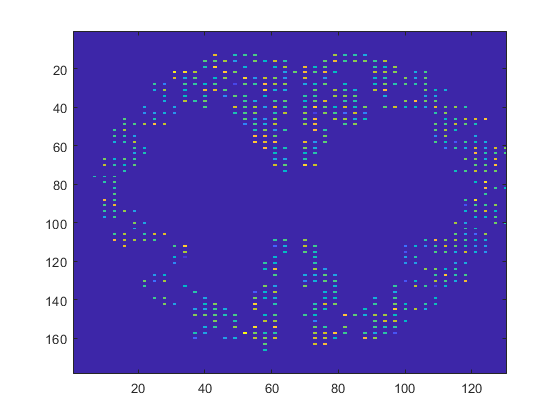

image = brain_image(:, :, 79, 20);
imagesc(image);

interpolate and reduce resolution

size(interpolate_brain_image)

ans =     65    89    65    98


interpolate_brain_image = permute(interpolate_brain_image, [2, 1, 3, 4]);
min(interpolate_brain_image, [], 'all')

ans = -64.9441

max(interpolate_brain_image, [], 'all')

ans = -57.2251

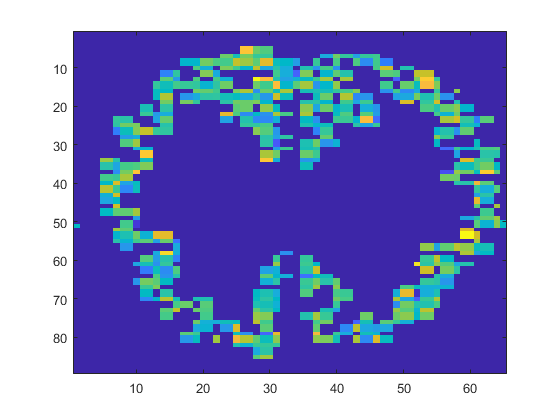

image = interpolate_brain_image(:, :, 38, 20);
imagesc(image);

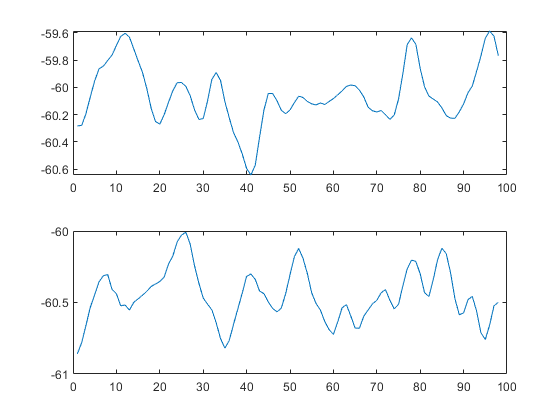

subplot(2, 1, 1);
temp = interpolate_brain_image(19, 19, 39, :);
plot(temp(:));
subplot(2, 1, 2)
temp = interpolate_brain_image (70, 20, 39, :);
plot(temp(:));

Velocity and visualization

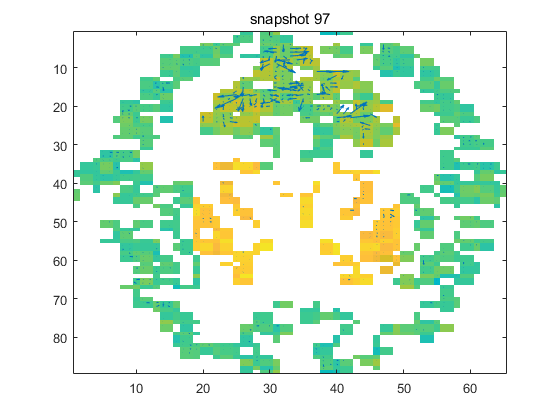

clearvars brain_image;
addpath('../Data/process_data/');
load('velocity_of_lfp_200hz.mat')
[M,N,~,T] = size(Ux);
interpolate_brain_image(interpolate_brain_image==0)=nan;
sigLims = [min(interpolate_brain_image(:)), max(interpolate_brain_image(:))];
[X,Y] = meshgrid(1:N,1:M);
% X=X+0.5; Y=Y+0.5;
z = 39;
dd = 1;
vidFps = 2;
fig = figure;
vidName = 'lfpVelocity';
vidTitle = strcat(vidName, datestr(now,'ddmm'), '_', ...
    datestr(now,'HHMM'), '.avi');
vidObj = VideoWriter(vidTitle);
vidObj.FrameRate = vidFps;
open(vidObj);
for t = 1:T
    signalGrid = interpolate_brain_image(:,:,z,t);
    h = imagesc(signalGrid, sigLims);
    set(h,'alphadata',~isnan(signalGrid));
%     colormap(gca, pmkmp_new) % parula
    vfColor = [0, 0, 0]; % [1, 1, 1]
    hold on % .*mask(:,:,z)
    quiver(X(1:dd:end,1:dd:end),Y(1:dd:end,1:dd:end),...
        Ux(1:dd:end,1:dd:end,z,t),...
        Uy(1:dd:end,1:dd:end,z,t), 3);
    set(gca,'YDir','reverse');
    hold off
    title(sprintf('snapshot %g', t))
    writeVideo(vidObj, im2frame(print(fig,'-RGBImage')));
end

close(vidObj);
